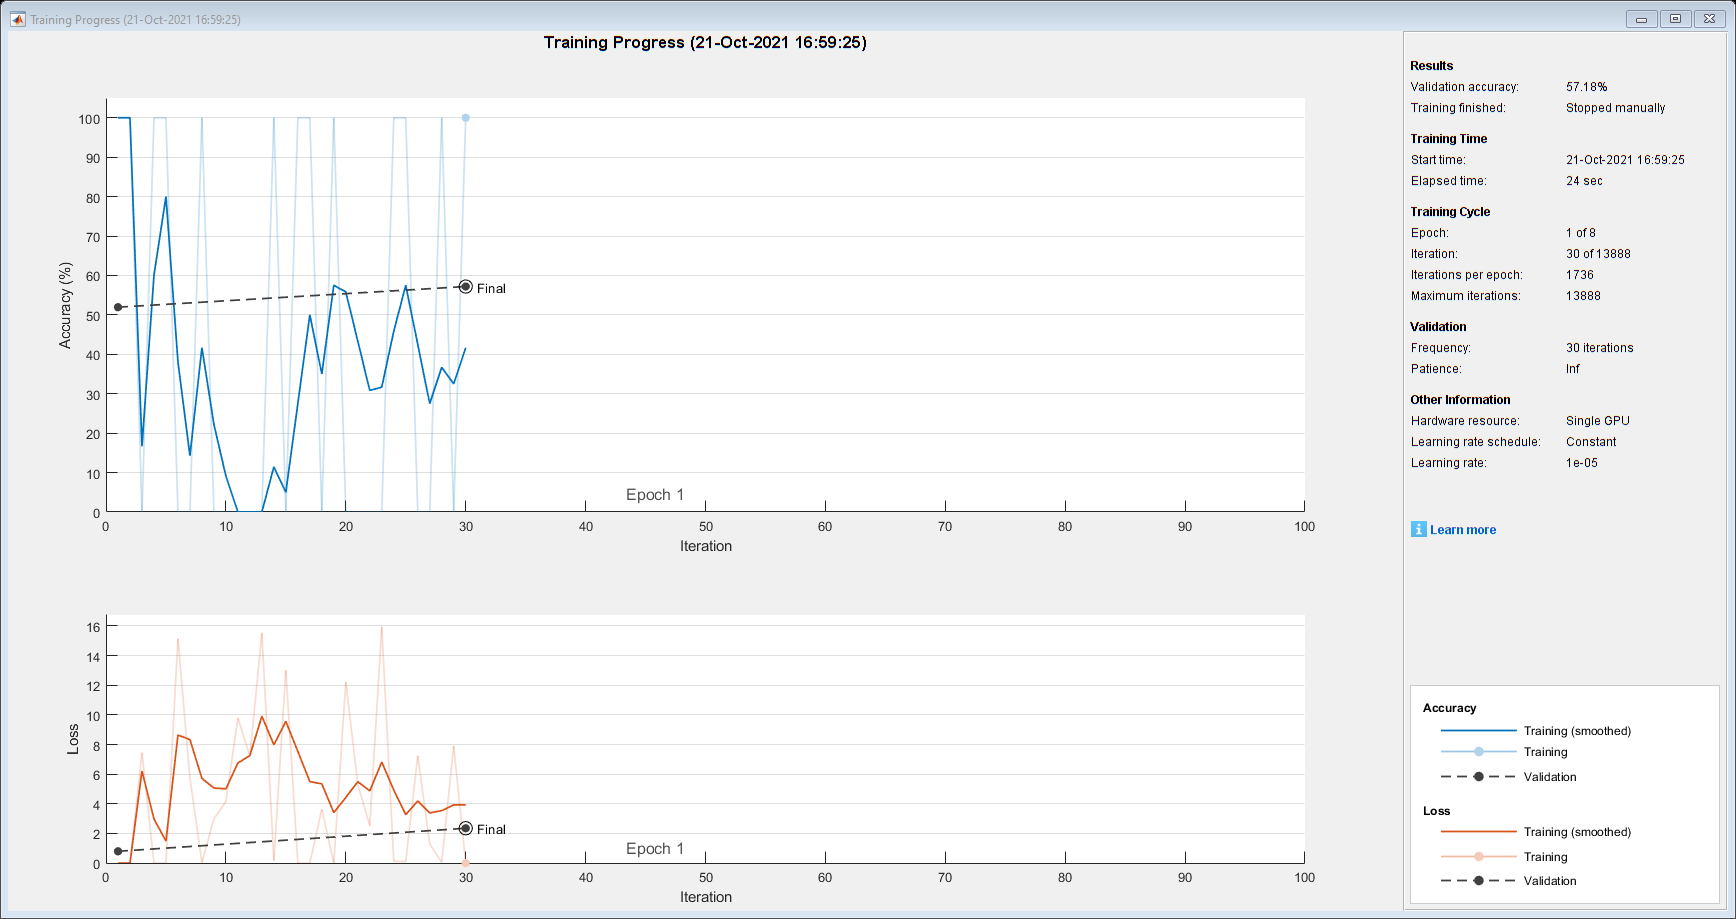

clear all
datapath='C:\Users\Justi\OneDrive\Masaüstü\Matlab Uyg\lowDataset';

imds=imageDatastore(datapath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

[imdsTrain,imdsValidation]=splitEachLabel(imds,0.7);

augimdsTrain=augmentedImageDatastore([227 227],imdsTrain);

augimdsValidation=augmentedImageDatastore([227 227],imdsValidation);

% Katmanlar 16 katman deneme
% layers = [
%     imageInputLayer([227 227 3],"Name","Resimler")
%     
%     convolution2dLayer([3 3],32,"Name","conv_1","Padding","same")
%     reluLayer("Name","relu_1")
%     crossChannelNormalizationLayer(5,"Name","crossnorm_1")
%     maxPooling2dLayer([5 5],"Name","maxpool_1","Padding","same")
%    
%     convolution2dLayer([3 3],32,"Name","conv_2","Padding","same")
%     reluLayer("Name","relu_2")
%     crossChannelNormalizationLayer(5,"Name","crossnorm_2")
%     maxPooling2dLayer([5 5],"Name","maxpool_2","Padding","same")
%     
%     convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
%     reluLayer("Name","relu_3")
%     crossChannelNormalizationLayer(5,"Name","crossnorm_3")
%     maxPooling2dLayer([5 5],"Name","maxpool_3","Padding","same")
%     
%     fullyConnectedLayer(2,"Name","fc")
%     softmaxLayer("Name","softmax")
%     classificationLayer("Name","classoutput")];

%Alexnet Baz alınarak geliştirilen
layers = [
    imageInputLayer([227 227 3],"Name","data")
    
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4])
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2","Stride",[2 2])
    
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu3")
    
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu4")
    
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu5")
    maxPooling2dLayer([3 3],"Name","pool5","Stride",[2 2])
    
    fullyConnectedLayer(4096,"Name","fc6","BiasLearnRateFactor",2)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","BiasLearnRateFactor",2)
    reluLayer("Name","relu7")
    
    fullyConnectedLayer(4096,"Name","fc8","BiasLearnRateFactor",2)
    reluLayer("Name","relu8")
    
    dropoutLayer(0.5,"Name","drop7")
    
    fullyConnectedLayer(2,"Name","fc9","BiasLearnRateFactor",2)
    softmaxLayer("Name","prob")
    classificationLayer("Name","output")];

% Ayarlar
opts = trainingOptions('sgdm', ...
    'LearnRateSchedule', 'none',...
    'InitialLearnRate', .00001,... 
    'MaxEpochs', 8, ...
    "ValidationData", augimdsValidation,...
     'Verbose',false, ...
     'ValidationFrequency',30, ...
    'MiniBatchSize', 1, ...
    'Plots','training-progress');


% Eğitim Kısmı
net=trainNetwork(augimdsTrain,layers,opts);